**Por favor, antes de realizar la actividad cambie el nombre del live script a uno que contenga las iniciales de los integrantes del grupo. Esto me permitirá diferenciar los archivos entregados en plataforma. De la misma manera, no olvide  ajustar el nombre del modelo a desarrollar en Simulink a fin de que incluya las iniciales de las personas que lo presentan.**

# **Logaritmos en Matlab**

En esta actividad, usted desarrollará las instrucciones para obtener los valores que se solicitan en cada punto

Nombre 1:Danna Xiomara Diaz Perdomo

Nombre 2: Juan Jose Fajardo Sanchez

## Part I

(3 points)

       1 . Cree un vector x de 100 elementos 1 hasta 1000000 con la función linspace

 X = linspace(1,1e6,100)

X =            1       10102       20203       30304       40405       50506       60607       70708       80809       90910      101011      111112      121213      131314      141415      151516      161617      171718      181819      191920      202021      212122      222223      232324      242425      252526      262627      272728      282829      292930      303031      313132      323233      333334      343435      353536      363637      373738      383839      393940      404041      414142      424243      434344      444445      454546      464647      474748      484849      494950


        2.  Cree un vector y de 100 elementos 1 hasta 1000000 con la función logspace

Y = logspace(1,6,100)

Y = 1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0015    0.0017    0.0019    0.0021    0.0024    0.0027    0.0030


        3.  ¿Cómo se diferencian los vectores x y y creados en los pasos 2 y 3?

Respuesta: El vector X genera valores lineales en contranste del vector Y que genera valores logaritmicos grandes por lo que el valor que retorna es un inf (infinito), este método es utilizado cuando se trabaja con resonancia debido a que cuando se grafica se quiere observar el comportamiento a bajas y grandes frecuencias. 

        4. Realice 3 graficos utilzando las funciones plot, semilogx, y loglog de la función f(x) = x^2. Por favor utilice la instrucción tiledlayout para crear en la parte superior la grafica con la función plot, seguida el gráfico con la instrucción semilog y por último la función loglog

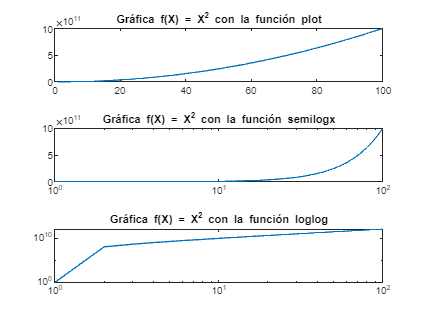

S = X.^2;
tiledlayout(3,1)
 
nexttile;
plot(S)
title('Gráfica f(X) = X^2 con la función plot')

nexttile;
semilogx(S)
title('Gráfica f(X) = X^2 con la función semilogx')

nexttile;
loglog(S)
title('Gráfica f(X) = X^2 con la función loglog')

## Part II

(7 points)

En sesiones presenciales anteriores se vieron circuitos en serie y paralelo resonantes. 

- Diseñe un circuito resonante (un serie y uno paralelo) que presente una frecuencia de resonancia al rededor de los 65 kHz. 

- Cree un modelo en Simulink y verifique que la condición de resonancia a 65 kHz

- Utilice este live script para crear un vector de frecuencias desde 1 Hz hasta 1 MHz logaritmicamente espaciado de al menos 100 valores. Tenga presente el paso 2 de la parte I.

- Utilice el vector creado en el paso 3 (de esta sección) para ejecutar la simulación del circuito resonante y registrar las magnitudes de interés en los circuitos resonantes para las 100 frecuencias del vector de frecuencia creada en el paso 3. Tenga presente las clases previas para poder escoger las magnitudes de interés. **Las magnitudes escogidas deben exportarse de manera automática a Matlab para que puedan ser accesibles desde el Live script**

- Utilice el tiledlayout para graficar:

I. Para el circuito Serie

            a. corriente vs frecuencia

            b. Desfase de la corriente vs frecuencia 

            c. Voltaje en el inductor vs frecuencia 

            d. Voltaje en el capacitor vs frecuencia 

            e. Impedancia vs frecuencia (Teóricamente no por simulación)

            f. Admitancia vs frecuencia (Teóricamente no por simulación)

II. Para el circuito Paralelo

            a. Corriente de la fuente vs frecuencia

            b. Desfase de la corriente de la fuente vs frecuencia 

            c. Corriente de R, L y C vs frecuencia 

            d. Impedancia vs frecuencia (Teóricamente no por simulación)

            e. Admitancia vs frecuencia (Teóricamente no por simulación)

Consideraciones:

a. Aunque no se indica el tipo de gráfica a desarrollar, (lineal, semilog, loglog) usted debe seleccionar aquella que mejor pueda resaltar el comportamiento del circuito

Nota: 

- Recuerde anexar el modelo en simulink desarrollado

- Usted debe presentar y sustentar la actividad al final de la sesión. 

- No comparta el código creado.

% clc
% clear
% close all

R = 5;
Fs = 65e3;
V = 10;
L = 10e-6;
LC = (1/(2*pi*Fs))^2;
C = LC/L;
F = logspace(4,6,100);
Xl= 1./(2*pi*F*L)*(1j);
Xc= (2*pi*F.*C)*(-1j);

Impedancia_Total_paralelo= (R+ Xl + Xc);
Impedancia= abs(Impedancia_Total_paralelo);
Admitancia= 1./Impedancia;

F(41) = Fs;

magnitude_current_series =  zeros(1,100);
Angle_current_series = zeros(1,100);
inductor_voltage_series = zeros(1,100);
capacitor_voltage_series = zeros(1,100);

Magnitude_current_paralelo = zeros(1,100);
Angle_current_paralelo = zeros(1,100);
Resistence_current_paralelo = zeros(1,100);
Inductor_current_paralelo = zeros(1,100);
Capacitor_current_paralelo = zeros(1,100);
  
for d = 1:100
    
    Frequency = F(d);

    Information = sim('PARALELO.slx');
    Information2 = sim('SERIE.slx');
    
    magnitude_current_series(d) = Information2.logsout{4}.Values.Data(end);

    Angle_current_series(d) = Information2.logsout{3}.Values.Data(end);

    inductor_voltage_series(d) = Information2.logsout{1}.Values.Data(end);

    capacitor_voltage_series(d) = Information2.logsout{2}.Values.Data(end);

    Magnitude_current_paralelo(d) = Information.logsout{5}.Values.Data(end);

    Angle_current_paralelo(d) = Information.logsout{4}.Values.Data(end);

    Resistence_current_paralelo(d) = Information.logsout{1}.Values.Data(end);

    Inductor_current_paralelo(d) = Information.logsout{2}.Values.Data(end);
    
    Capacitor_current_paralelo(d) = Information.logsout{3}.Values.Data(end);
end

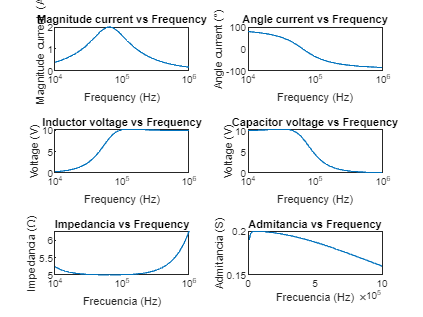


% Circuito en serie:

tiledlayout(3,2)

nexttile
semilogx(F,magnitude_current_series)
title('Magnitude current vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Magnitude current  (A)')

nexttile
semilogx(F,Angle_current_series)
title('Angle current vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Angle current (°)')

nexttile
semilogx(F,inductor_voltage_series)
title('Inductor voltage vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Voltage (V)')

nexttile
semilogx(F,capacitor_voltage_series)
title('Capacitor voltage vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Voltage (V)')

nexttile
semilogx(F,Impedancia)
title("Impedancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Impedancia (Ω)")

nexttile
plot(F,Admitancia)
title("Admitancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Admitancia (S)")
hold off

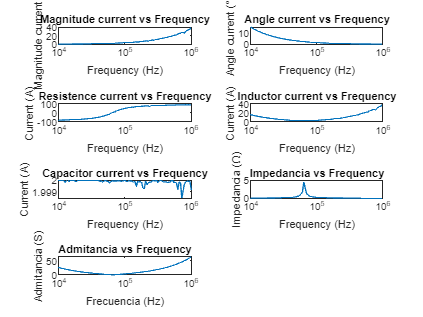

% Circuito paralelo

F = logspace(4,6,100);
Xl= 1./(2*pi*F*L)*(1j);
Xc= (2*pi*F.*C)*(-1j);

Impedancia_Total_paralelo= 1./((1/R)+(1./Xc)+(1./Xl));
Impedancia_paralelo= abs(Impedancia_Total_paralelo);
Admitancia_paralelo= 1./Impedancia_paralelo;


Paralelo = tiledlayout(4,2);

nexttile
semilogx(F,Magnitude_current_paralelo)
title('Magnitude current vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Magnitude current (A)')

nexttile
semilogx(F,Angle_current_paralelo)
title('Angle current vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Angle current (°)')

nexttile
semilogx(F,Resistence_current_paralelo)
title('Resistence current vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Current (A)')
    
nexttile
semilogx(F,Inductor_current_paralelo)
title('Inductor current vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Current (A)')

nexttile
semilogx(F,Capacitor_current_paralelo)
title('Capacitor current vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Current (A)')

nexttile
semilogx(F,Impedancia_paralelo)
title('Impedancia vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Impedancia (Ω)')

nexttile
semilogx(F,Admitancia_paralelo)
title("Admitancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Admitancia (S)")